# Homework 2

ECE 45 - Your Name Here 

New text here 

## Problem 1

Consider the following CT signal . 

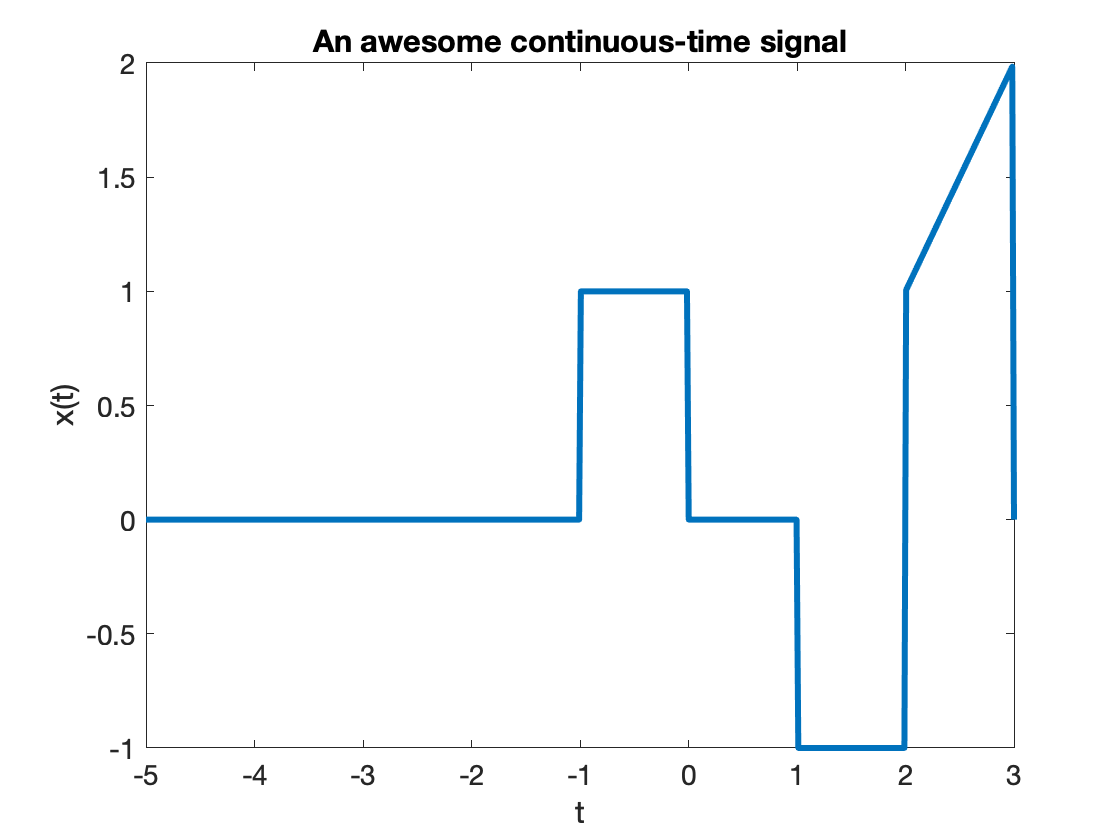

figure;clf; 
t=linspace(-5,3,500);
ct_fun = ct_function(t);
plot(t,ct_fun,'-',...
'LineWidth', 3);
xlabel('t');
ylabel('x(t)');
set(gca,'FontSize',14);
title('An awesome continuous-time signal')

### Part (a)

Plot $x(t-1)$

### Part (b)

Plot $2x(2-t)$

### Part (c)

Plot $x(3t-1)+1$

### Part (d)

Plot $x(t/3-1)+1$

### Part (e)

Even part of $x(t)$

### Part (f)

Odd part of $x(t)$

### Part (g)

 
$$x(t) u(t)$$


## Appendix - Functions

function my_ct_fun = ct_function(t)
% using a for loop, which is not efficient in MATLAB but OK for a quick
% calculation
    for c = 1:length(t)
        switch true % this is a hack to get switch to work for intervals, see help on switch
            case t(c)<-1
                my_ct_fun(c) = 0;
            case t(c)>=-1 && t(c)<0
                my_ct_fun(c) = 1;
            case t(c)>=0 && t(c)<1
                my_ct_fun(c) = 0;
            case (t(c)>=1)&&(t(c)<2)
                my_ct_fun(c) = -1;
            case (t(c)>=2)&&(t(c)<3)
                my_ct_fun(c) = t(c)-1;
           case t(c)>=3
                my_ct_fun(c) = 0;
        end
    end % for c
end % fucntion (edited) 